# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

middle = [
    imageInputLayer([270 270 3],"Name","imageinput")
    convolution2dLayer([3 3],24,"Name","conv_1","Padding","same")
    convolution2dLayer([1 1],3,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_1")
    convolution2dLayer([1 1],3,"Name","conv_3","Padding","same")
    convolution2dLayer([3 3],3,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([15 15],"Name","maxpool","Padding","same","Stride",[15 15])
    convolution2dLayer([3 3],33,"Name","conv_5","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],3,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_3")
    convolution2dLayer([1 1],4,"Name","conv_7","Padding","same")
    convolution2dLayer([3 3],4,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],4,"Name","conv_9","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],3,"Name","conv_10","Padding","same")
    reluLayer("Name","relu_5")
    convolution2dLayer([1 1],4,"Name","conv_11","Padding","same")
    convolution2dLayer([3 3],4,"Name","conv_12","Padding","same")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],3,"Name","conv_13","Padding","same")
    softmaxLayer("Name","softmax")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat")
    
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"conv_5","conv_6");
lgraph = connectLayers(lgraph,"conv_5","conv_10");
lgraph = connectLayers(lgraph,"conv_9","depthcat/in2");
lgraph = connectLayers(lgraph,"softmax","depthcat/in1");

## Plot Layers

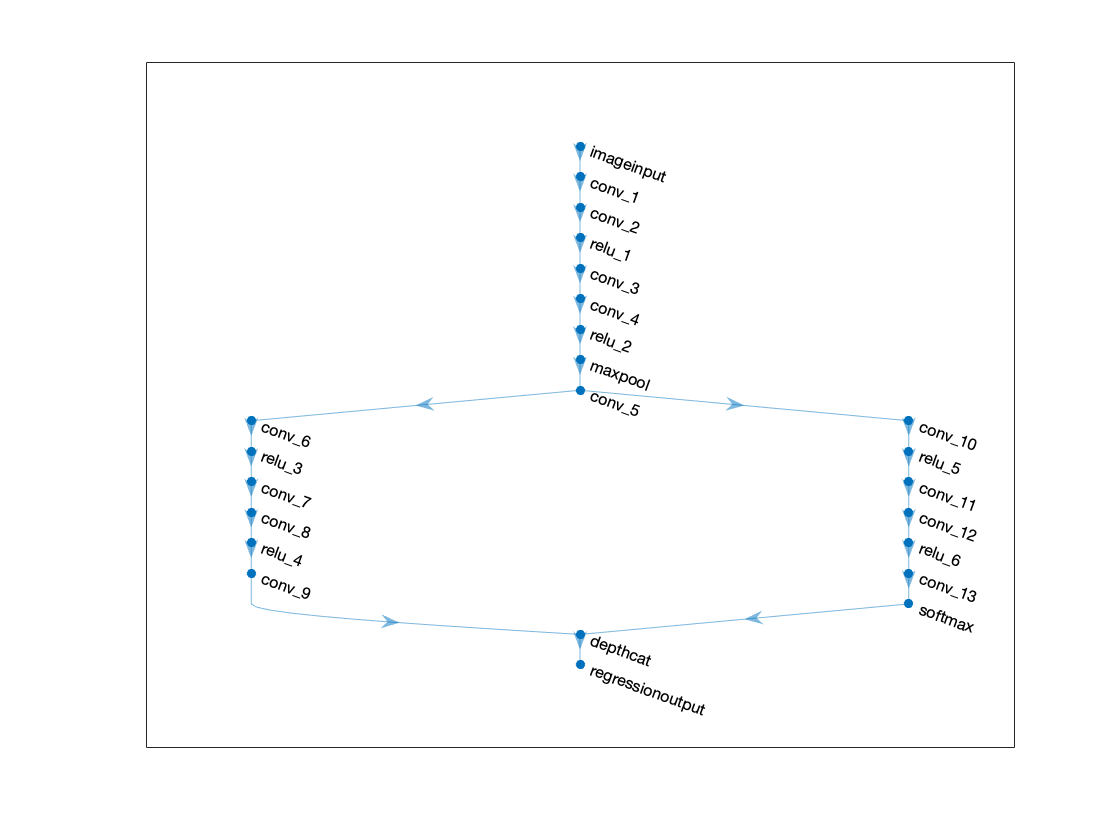

plot(lgraph);

## Predict

%  analyzeNetwork(lgraph)

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0001, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MaxEpochs', 50);

x = zeros([270, 270, 3]);

count = 1;
files = imds.Files; 

for img = 1:3
    img_f = imresize(imread(files{img}), [270, 270]); 
    size(img_f)
    x(:, :, :, img) = img_f; 
    count = count + 1; 
end 

ans =    270   270     3


ans =    270   270     3


ans =    270   270     3


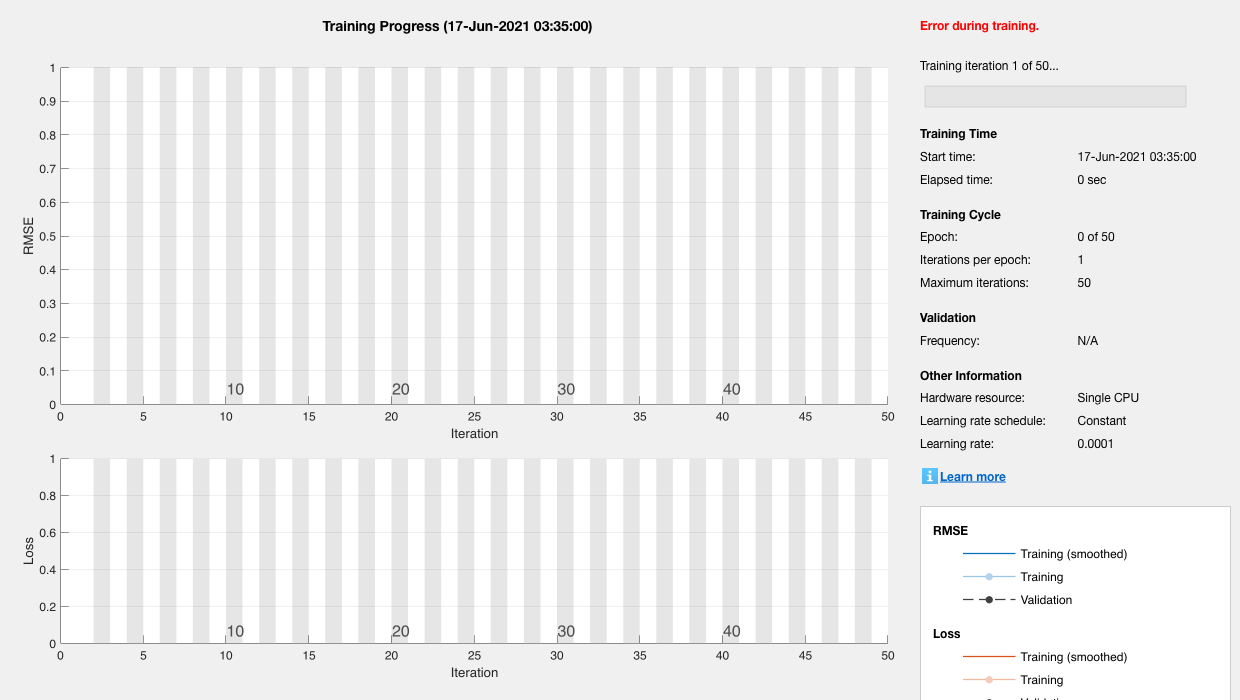

Error using trainNetwork (line 184)
Size arguments must be real integers.

Caused by:
    Error using reshape
    Size arguments must be real integers.


net = trainNetwork(x,y_stack,layers_6,options);